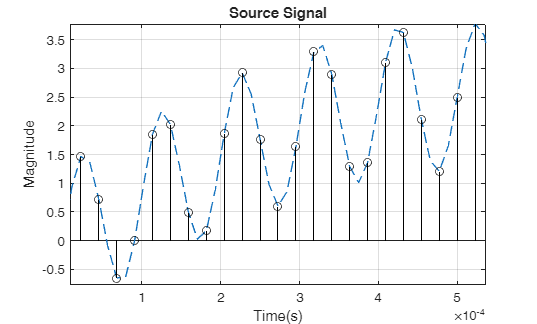

% creating the sine wave of 10khz
t = 0:1/(88*1000):1;                % time vector for continuous time signal
fs = 44*(1000);                     % sampling frequency 48kHz
ts = 0:(1/fs):1;                    % time vector(n) for digitally sampled signal
f1 = 10000;                         % signal1 frequency 10kHz
f2 = 500;                           % signal2 frequency 5khz

st = 1.3*sin(2*pi*f1*t) + 2.5*sin(2*pi*f2*t);   % CTS
s = 1.3*sin(2*pi*f1*ts) + 2.5*sin(2*pi*f2*ts);  % DTS

% s = 1.3*sin(2*pi*f1*ts)
% st = 1.3*sin(2*pi*f1*t)

% plotting source signal in time domain
figure();
plot(t(1:50),st(1:50), "--");
hold on;
stem(ts(1:25), s(1:25), 'Color',"black");
hold off;
xlabel("Time(s)");
ylabel("Magnitude");
title("Source Signal");
grid on;

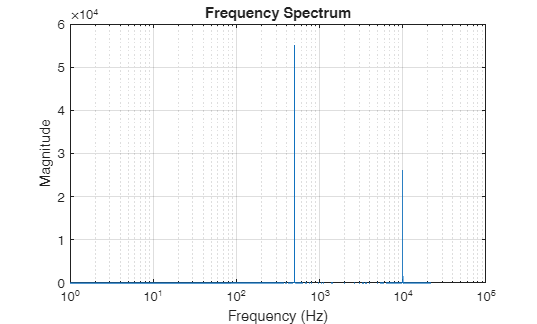


% Compute and plot the single-sided frequency spectrum
spectrum = abs(fft(s));
frequency = 0:fs/length(ts):22*1000;

figure();
plot(frequency, spectrum(1:length(frequency)));
xlabel("Frequency (Hz)");
ylabel("Magnitude");
title("Frequency Spectrum");
grid on;
xscale log

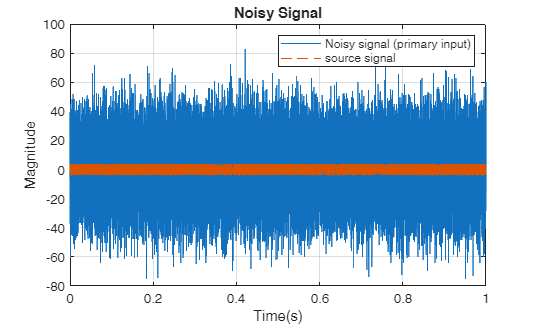

% adding noise to the signal

hum_noise = 0.7*sin(2*pi*50*ts);            % 50Hz humm noise due to AC supply
white_noise = 2.3*randn(size(s));           % random white noise distributed across all frequencies
noise = hum_noise + 4.2*white_noise;        % total noise signal to be added to the source signal

noisy_signal = s + 2*noise;

figure();
plot(ts, noisy_signal)
hold on;
grid on;
plot(ts, s, "--");
hold off;
xlabel("Time(s)");
ylabel("Magnitude");
title("Noisy Signal");
legend("Noisy signal (primary input)", "source signal")

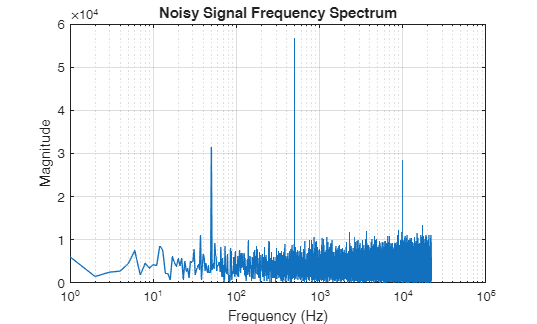


spectrum_noisy_signal = abs(fft(noisy_signal));
figure();
plot(frequency, spectrum_noisy_signal(1:length(frequency)));
xscale log
xlabel("Frequency (Hz)");
ylabel("Magnitude");
title("Noisy Signal Frequency Spectrum");
grid on;

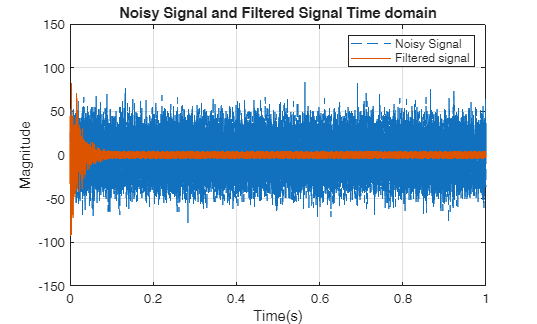

% output filtered signal from LMS filter function
output_signal = lms_adaptive_filter_func(noisy_signal, noise, 1e-5);

% noisy signal vs filtered signal time domain plot
figure();
plot(ts, noisy_signal, "--");
grid on;
hold on;
plot(ts, output_signal);
hold off;
legend("Noisy Signal", "Filtered signal");
xlabel("Time(s)");
ylabel("Magnitude");
title("Noisy Signal and Filtered Signal Time domain");
ylim([-150, 150])

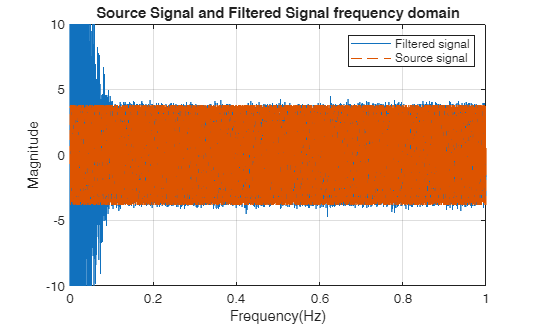


% source signal vs filtered signal time domain plot
figure();
plot(ts, output_signal);
hold on;
grid on;
plot(ts, s, "--");
hold off;
legend("Filtered signal", "Source signal")
xlabel("Frequency(Hz)");
ylabel("Magnitude");
title("Source Signal and Filtered Signal frequency domain");
ylim([-10, 10])

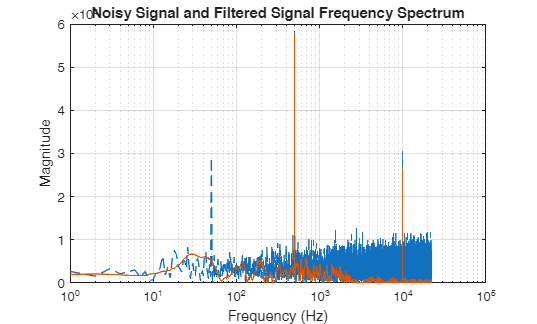


% noisy signal vs filtered signal frequency domain plot
filtered_spectrum = abs(fft(output_signal));
figure();
plot(frequency, spectrum_noisy_signal(1:length(frequency)), "--");
hold on;
plot(frequency, filtered_spectrum(1:length(frequency)));
hold off;
xlabel("Frequency (Hz)");
ylabel("Magnitude");
title("Noisy Signal and Filtered Signal Frequency Spectrum");
grid on;
xscale log

% snr calculations and analysis
snrNoisy = snr(s, noisy_signal - s)

snrNoisy = -19.7374

snrFiltered = snr(s, output_signal - s)

snrFiltered = -6.6376

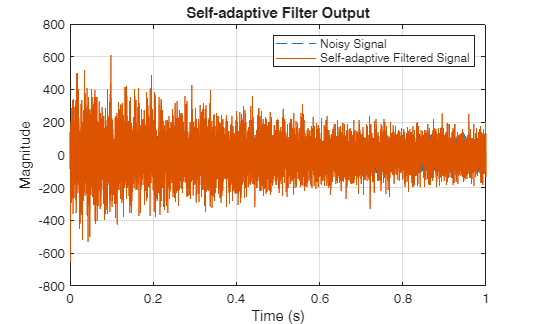

% self adaptive filter
% delay_time = 0.001;
% delay_samples = delay_time*fs;
% 
% delayed_signal = [zeros(1, delay_samples), noisy_signal(1:end - delay_samples)];
% 
% self_adaptive_filter_op = lms_adaptive_filter_func(noisy_signal, delayed_signal, 2e-8);
% figure();
% plot(ts, noisy_signal, "--");
% hold on;
% plot(ts, self_adaptive_filter_op);
% hold off;
% grid on;
% legend("Noisy Signal", "Self-adaptive Filtered Signal");
% xlabel("Time (s)");
% ylabel("Magnitude");
% title("Self-adaptive Filter Output");


snr_primary = snr(s, noisy_signal - s)

snr_primary = -25.7083

snr_filter_op = snr(s, self_adaptive_filter_op - s)

snr_filter_op = -33.9847